## Calculation of initialization contrast and ODMR contrast

### Initialization contrast

clear 
clc
close all

#### Access n_res at t = 20

load('NV_population_data.mat', 'n_res', 't');

n_res_20 = zeros(7,1);
for i = 1:7
    n_res_temp = n_res(:, i);
    n_res_20(i, 1) = n_res_temp(end);
end
disp(sum(n_res_20))

    1.0000



disp(n_res_20)

    0.6637
    0.1276
    0.1276
    0.0165
    0.0017
    0.0017
    0.0613



#### Simulate for 5 more us with beta = 0

init = n_res_20;

K0 = zeros(7,7);
 
beta = 0;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;
disp(K0)

         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
   63.0000         0         0         0         0         0   13.0000
         0   63.0000         0         0         0         0   80.0000
         0         0   63.0000         0         0         0   80.0000
    3.5000    2.2000    2.2000         0         0         0         0



#### The rate equations

code provided by Professor Takahashi

K = K0;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

#### Solve the rate equations numerically using ode45 (from t = 0 to t = 5)

[t_2, n_res_2] = ode45(odes, [0:1e-3:5000e-3], init);

#### Plot the solutions

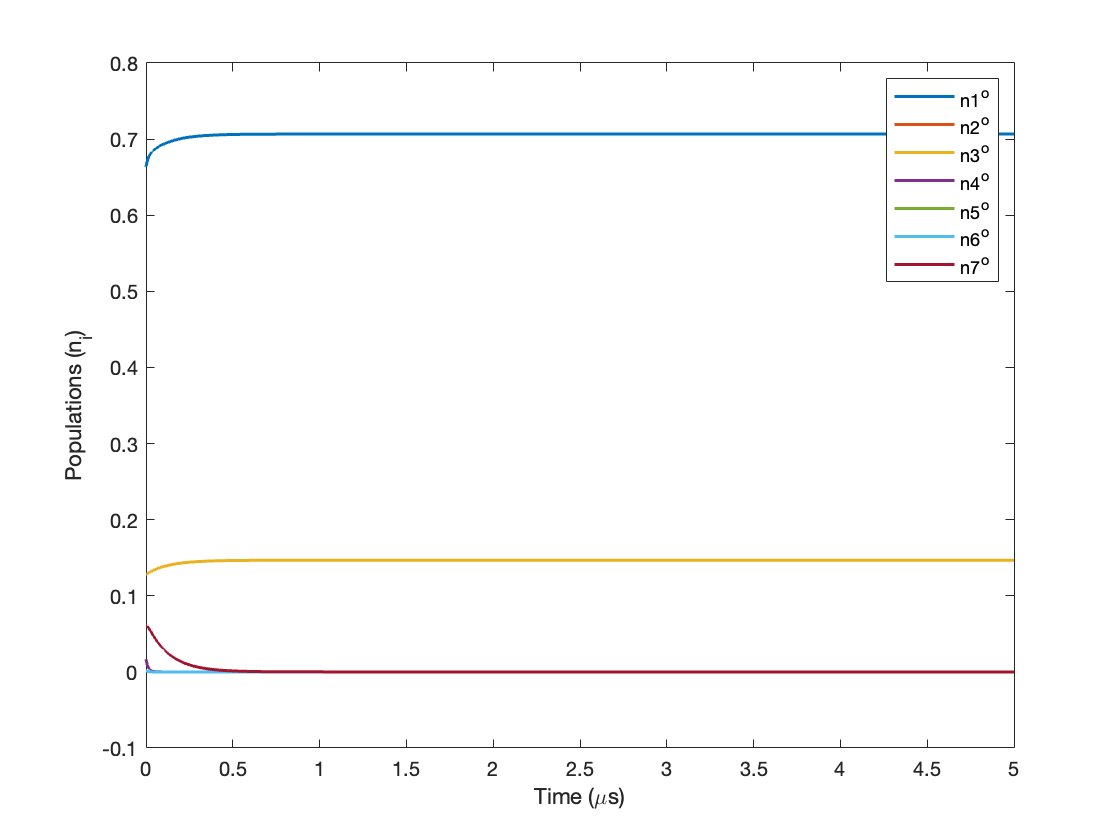

plot(t_2, n_res_2, "LineWidth", 1.5);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o", "n4^o", "n5^o", "n6^o", "n7^o");

#### Calculate the initialization contrast: init_contrast

n1_temp = n_res_2(:, 1);
n1_25 = n1_temp(end)

n1_25 = 0.7066


n2_temp = n_res_2(:, 2);
n2_25 = n2_temp(end)

n2_25 = 0.1467

init_contrast = (n1_25 - n2_25)/(n1_25 + n2_25)

init_contrast = 0.6562

### ODMR Contrast

#### Simulation of state 1

initial conditions: n_i = /delta^1_i

init_1 = [1; 0; 0; 0; 0; 0; 0];

K0 = zeros(7,7);
 
beta = 0.03;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;
disp(K0)

         0         0         0    1.8900         0         0         0
         0         0         0         0    1.8900         0         0
         0         0         0         0         0    1.8900         0
   63.0000         0         0         0         0         0   13.0000
         0   63.0000         0         0         0         0   80.0000
         0         0   63.0000         0         0         0   80.0000
    3.5000    2.2000    2.2000         0         0         0         0



K = K0;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

[t_3, n_res_3] = ode45(odes, [0:1e-3:25000e-3], init_1);

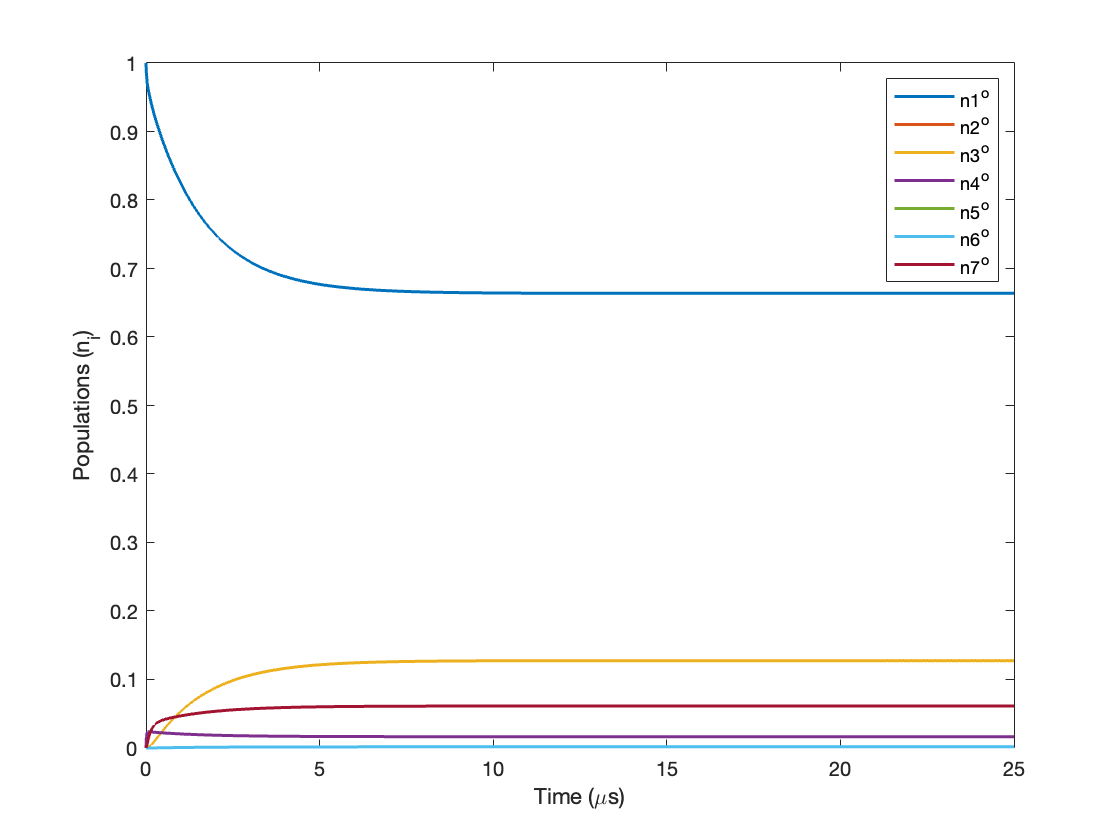

plot(t_3, n_res_3, "LineWidth", 1.5);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o", "n4^o", "n5^o", "n6^o", "n7^o");

n_1_4 = n_res_3(:, 4);
n_1_5 = n_res_3(:, 5);
n_1_6 = n_res_3(:, 6);
sum_1 = n_1_6 + n_1_5 + n_1_4;

sum_1 =          0
    0.0018
    0.0035
    0.0051
    0.0065
    0.0078
    0.0091
    0.0102
    0.0113
    0.0122


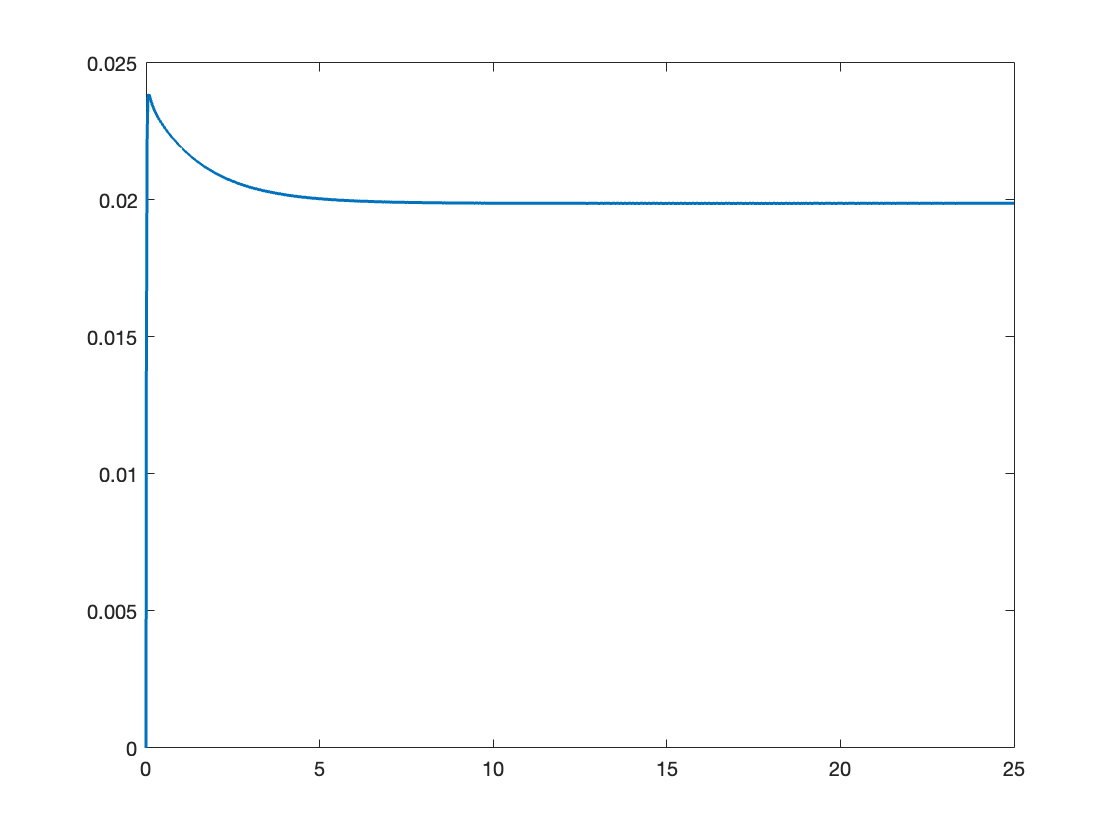

plot(t_3, sum_1, "LineWidth", 1.5);

#### Simulation of state 1

initial conditions: n_i = /delta^2_i

init_2 = [0; 1; 0; 0; 0; 0; 0];

[t_4, n_res_4] = ode45(odes, [0:1e-3:25000e-3], init_2);

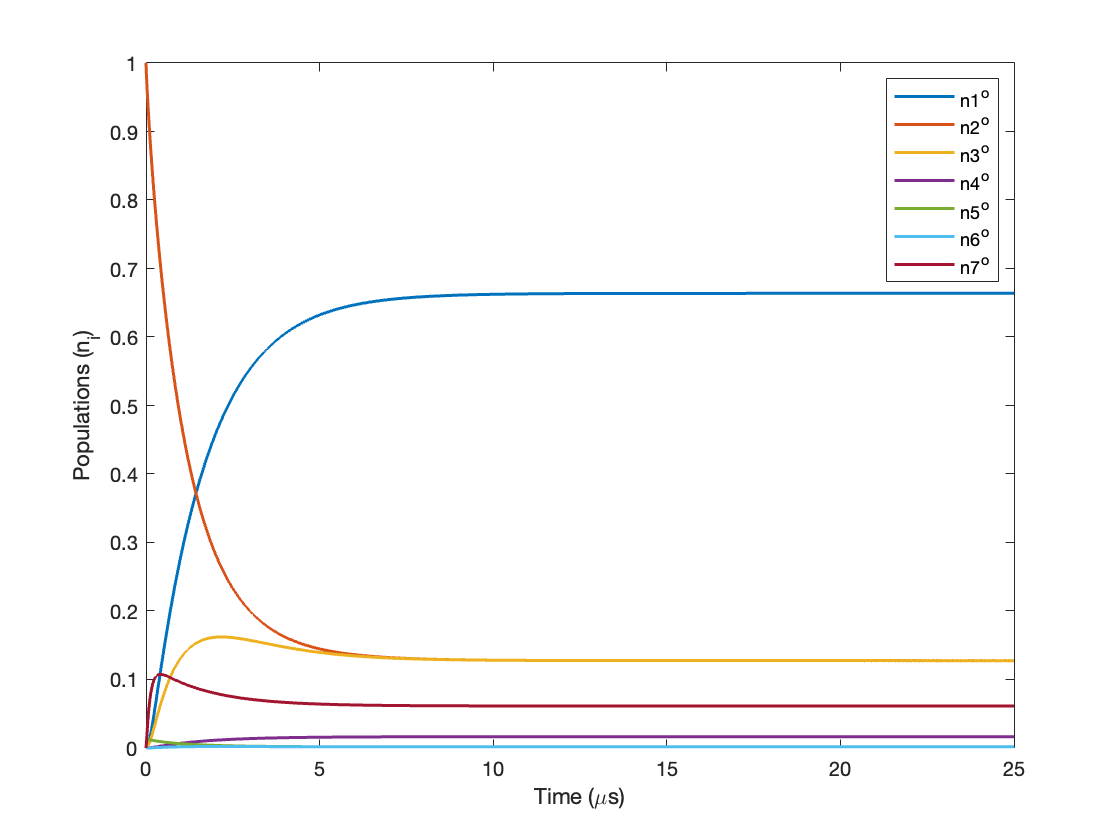

plot(t_4, n_res_4, "LineWidth", 1.5);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o", "n4^o", "n5^o", "n6^o", "n7^o");

n_2_4 = n_res_4(:, 4);
n_2_5 = n_res_4(:, 5);
n_2_6 = n_res_4(:, 6);
sum_2 = n_2_6 + n_2_5 + n_2_4

sum_2 =          0
    0.0018
    0.0033
    0.0046
    0.0057
    0.0067
    0.0076
    0.0083
    0.0089
    0.0095


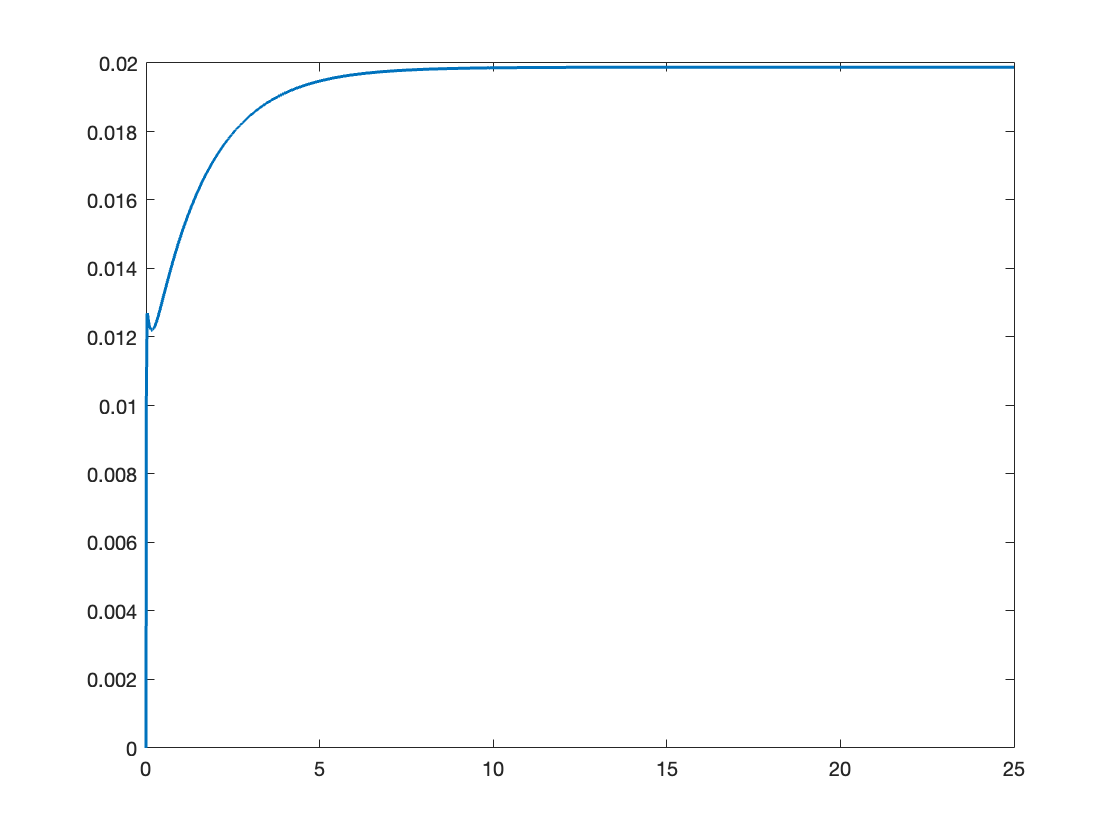

plot(t_4, sum_2, "LineWidth", 1.5);

#### Calculate the ODMR contrast

contrast_arr = abs(sum_2 - sum_1);
ODMR_contrast = max(contrast_arr)

ODMR_contrast = 0.0115

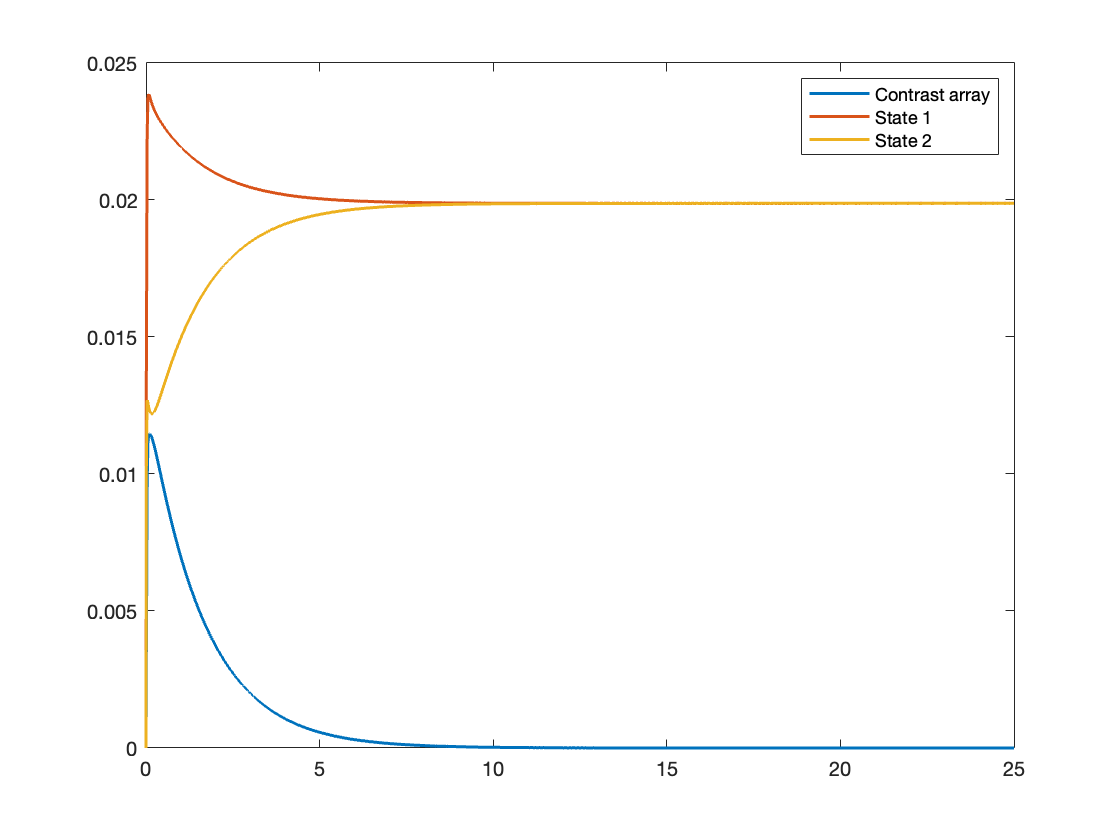

plot(t_4, contrast_arr, "LineWidth", 1.5);
hold on;
plot(t_3, sum_1, "LineWidth", 1.5);
hold on;
plot(t_4, sum_2, "LineWidth", 1.5);
hold off;
legend("Contrast array", "State 1", "State 2");

save('contrast_results');